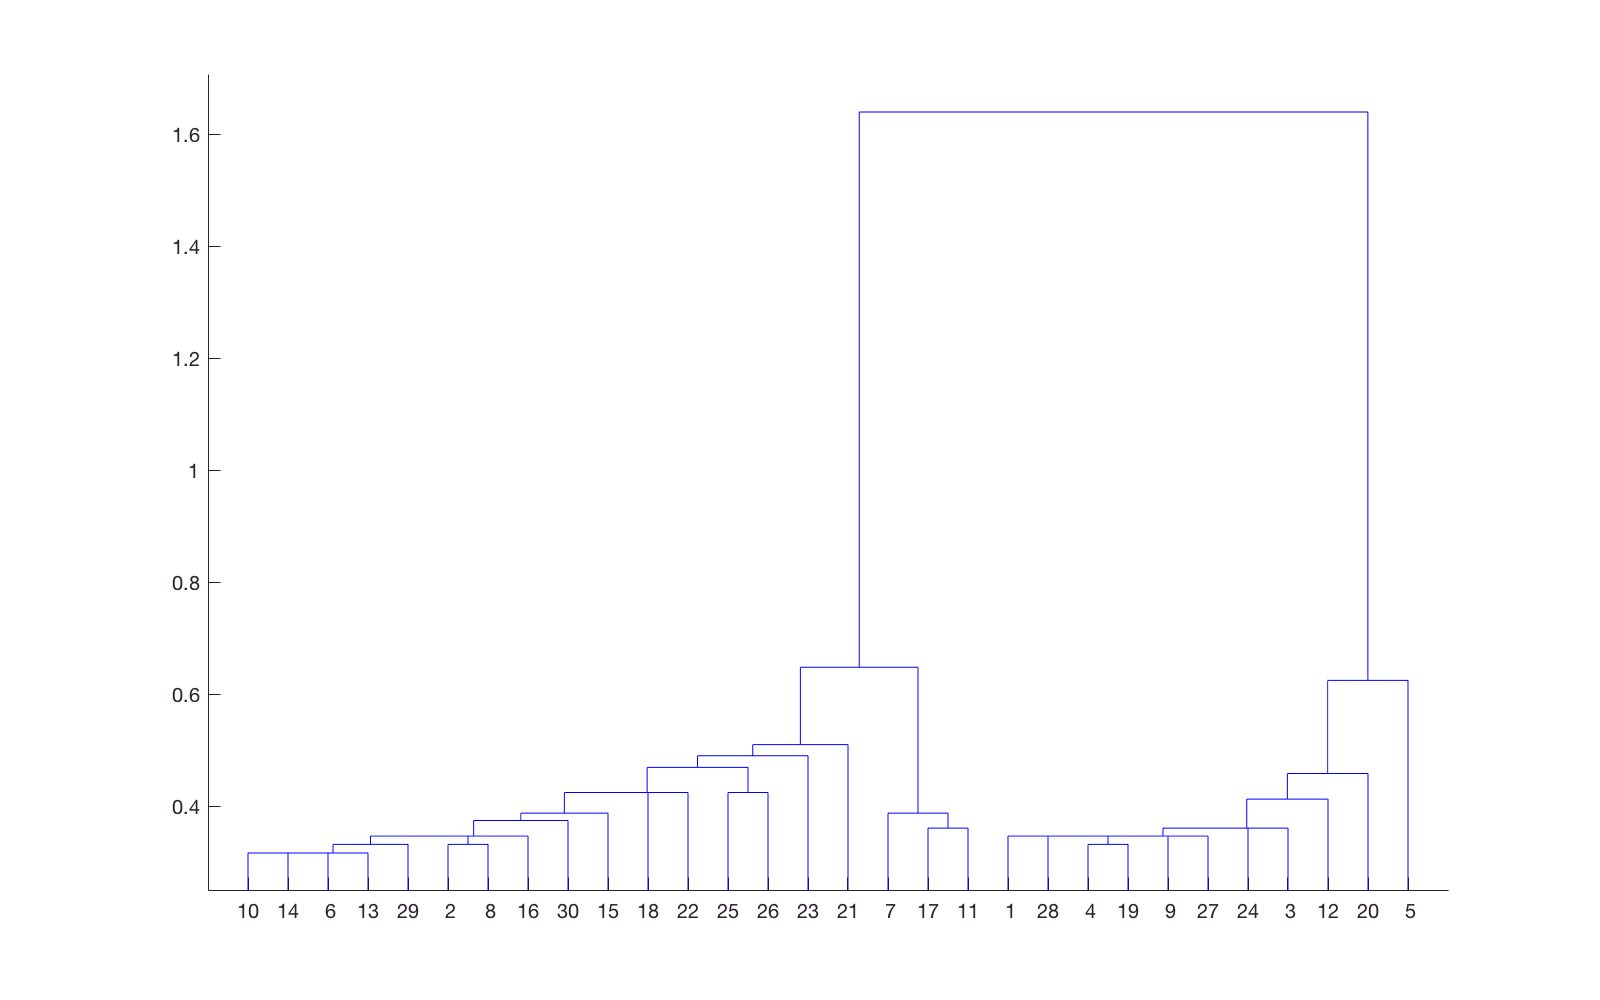

% Task 2.2

% read raw data
S = dlmread('wbsa0350.dat');

%% Hierachical Clustering

A = pdist(S); % calc distances

%disp(squareform(A)); % check matrix of A, optional
% Baue Clusterbaum aus Abstandsvektor auf
B = linkage(A); % build clustertree

dendrogram(B); % plot cluster tree

% --> Seems to be 4 by interpreting dendogram1

nocl = 4; % number of clusters, var can be used for the rest of script

HC = cluster(B,'maxclust',nocl);
%disp(HC);

HC1 = S(HC==1,:);
HC2 = S(HC==2,:);
HC3 = S(HC==3,:);
HC4 = S(HC==4,:);

% optional plotting, does not work
hold on
plot(HC1(:,1),HC1(:,2), 'ok')
plot(HC2(:,1),HC2(:,2), 'xk')
plot(HC3(:,1),HC3(:,2), '+k')
plot(HC4(:,1),HC4(:,2), 'vk')



[noelHC1,~] = size(HC1);
[noelHC2,~] = size(HC2);
[noelHC3,~] = size(HC3);
[noelHC4,~] = size(HC4);

fprintf('hierachical Clustering: Num Elements in clusters: %i, %i, %i,%i\n',noelHC1,noelHC2,noelHC3,noelHC4);

hierachical Clustering: Num Elements in clusters: 1, 49, 4,46


%% K-mean-Clustering

KM = kmeans(S, nocl); % use clusternum
KM1 = S(KM==1,:);
KM2 = S(KM==2,:);
KM3 = S(KM==3,:);
KM4 = S(KM==4,:);

[noelKM1,~] = size(KM1);
[noelKM2,~] = size(KM2);
[noelKM3,~] = size(KM3);
[noelKM4,~] = size(KM4);

fprintf('K-mean-clustering: num Elementes in clusters: %i, %i, %i,%i\n',noelKM1,noelKM2,noelKM3,noelKM4);

K-mean-clustering: num Elementes in clusters: 27, 24, 23,26


%% fuzzy k-mean clustering

centrS = zscore(S); % centralize data

[Z,U,J] = fcm(centrS,nocl); % do clustering: U := Zuordnungsmatrix

Iteration count = 1, obj. fcn = 123.823456
Iteration count = 2, obj. fcn = 94.331045
Iteration count = 3, obj. fcn = 71.075503
Iteration count = 4, obj. fcn = 49.719152
Iteration count = 5, obj. fcn = 48.110288
Iteration count = 6, obj. fcn = 47.947234
Iteration count = 7, obj. fcn = 47.301398
Iteration count = 8, obj. fcn = 45.266662
Iteration count = 9, obj. fcn = 42.659346
Iteration count = 10, obj. fcn = 40.249487
Iteration count = 11, obj. fcn = 38.318472
Iteration count = 12, obj. fcn = 37.629285
Iteration count = 13, obj. fcn = 37.485200
Iteration count = 14, obj. fcn = 37.459271
Iteration count = 15, obj. fcn = 37.453912
Iteration count = 16, obj. fcn = 37.452372
Iteration count = 17, obj. fcn = 37.451776
Iteration count = 18, obj. fcn = 37.451509
Iteration count = 19, obj. fcn = 37.451383
Iteration count = 20, obj. fcn = 37.451322
Iteration count = 21, obj. fcn = 37.451293
Iteration count = 22, obj. fcn = 37.451278
Iteration count = 23, obj. fcn = 37.451271



% Finde Datensaetze von denen mehr als ein Merkmal mehr als einem Datensatz
% zuzuordnen sind (>0.33) aus Zuordnungsmatrix
UBiggerThanThird = U(:,(sum(U>0.33) >= 2))

UBiggerThanThird =     0.3790    0.3959    0.4429    0.0457    0.5961    0.0256    0.0491    0.0487    0.5892    0.5068    0.4346    0.0297
    0.5363    0.5645    0.5039    0.0507    0.3574    0.0254    0.0556    0.0485    0.3317    0.4498    0.5006    0.0304
    0.0527    0.0238    0.0324    0.4905    0.0275    0.3766    0.5111    0.5242    0.0473    0.0259    0.0382    0.3443
    0.0321    0.0158    0.0209    0.4130    0.0190    0.5724    0.3843    0.3786    0.0318    0.0175    0.0267    0.5957



% values from data
SBiggerThanThird = S((sum(U>0.33) >= 2),:)

SBiggerThanThird =     5.1000    3.3000    1.7000    0.5000
    5.0000    3.4000    1.5000    0.2000
    5.0000    3.4000    1.6000    0.4000
    6.3000    2.3000    4.4000    1.3000
    5.2000    3.4000    1.4000    0.2000
    6.1000    2.8000    4.0000    1.3000
    6.2000    2.2000    4.5000    1.5000
    5.6000    3.0000    4.5000    1.5000
    5.0000    3.5000    1.6000    0.6000
    5.1000    3.4000    1.5000    0.2000


Datensaetze die nicht mehr als ein Drittel zu einem Cluster zuzuordnen sind:


% Datensaetze die nicht mehr als ein Drittel zu einem Cluster zuzuordnen sind
USmallerThanThird = U(:,unique(U<0.33))

USmallerThanThird =     0.0132
    0.0121
    0.1047
    0.8700


%values from Data
SSmallerThanThird = S(unique(U<0.33),:)

SSmallerThanThird =     6.1000    3.0000    4.6000    1.4000
